%% ========================================================================
%  EANN_MO_Pareto_accel_from_a_noGPU.m
%  ------------------------------------------------------------------------
%  ¿QUÉ HACE ESTE CÓDIGO?
%   • Red EANN (MLP 2 capas + cabeza residual) que mapea features de las
%     ÚLTIMAS 5 columnas de la matriz 'a'  ->  [k1..k5, c1..c5].
%   • Optimiza TODOS los pesos/sesgos de la red con evolución MULTI-OBJETIVO
%     (gamultiobj) en 2 FASES + refinamiento local con fmincon.
%   • 3 OBJETIVOS simultáneos:
%       f1: error temporal (aceleración) ar vs modelo (ponderado en el tiempo)
%       f2: alineación modal (picos espectrales) en aceleración (FFT puro MATLAB)
%       f3: regularización física (A*g<=b + suavidad + log-escala)
%   • Genera el FRENTE DE PARETO (3D + proyecciones 2D), selecciona "knee",
%     refina localmente y grafica aceleración por piso (Medida vs Modelo).
%   • Imprime los COEFICIENTES K y C finales.
%  ------------------------------------------------------------------------
%  ENTRADAS (archivo .mat):
%    a   [N×M]  : matriz de señales; se usan SOLO las 5 últimas columnas
%    ar  [N×5]  : aceleraciones medidas (por piso)
%    ab  [N×1]  : aceleración de base (excitación sísmica)
%    t   [N×1]  : tiempo
%    af  [N×M]  : aceleración filtrada por piso (se usarán las ÚLTIMAS 5 columnas)
%  SALIDAS:
%    - Figuras: Frente de Pareto + aceleración por piso (3 curvas)
%    - Archivo: EANN_MO_Q1_accel_result.mat con red y resultados
%    - Impresión por consola: tabla con K y C finales
%  ------------------------------------------------------------------------
%  NOTAS:
%    • Integrador Tustin sin lsim/MEX (seguro en parpool 'Processes').
%    • Código sin GPU.
% ========================================================================
tic
close all; clc; rng(1);

%% === Paralelo (solo PROCESOS) ==========================================
try
    p = gcp('nocreate');
    if isempty(p) || ~strcmpi(p.Type,'processes')
        if ~isempty(p), delete(p); end
        parpool('Processes');
    end
catch
    warning('Sin parpool; ejecuto en secuencial.');
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 12 workers.



%% ========================= CARGA DE DATOS ===============================
S = load('datosFiltradosSismoYOct8.mat','a','ar','ab','t','af');

a  = S.a;
ar = S.ar;
ab = S.ab;
t  = S.t;

assert(isvector(ab) && isvector(t) && size(ar,2)==5, ...
    'Se requieren: a (NxM), ar (Nx5), ab (Nx1), t (Nx1).');
N  = numel(ab); ab = ab(:); t = t(:);
assert(size(ar,1)==N && size(a,1)==N, 'Dimensiones inconsistentes (a/ar vs ab/t).');

% --- af: usar SIEMPRE las ÚLTIMAS 5 columnas ---
assert(isfield(S,'af'), 'El archivo MAT debe contener la variable ''af''.');
af = S.af;
assert(size(af,1)==N && size(af,2)>=5, ...
    'af debe ser N×M con M>=5. Tamaño actual: %s', mat2str(size(af)));
AF5 = af(:, end-4:end);   % N×5 (aceleración filtrada por piso, últimas 5 columnas)

% Tomamos las ÚLTIMAS 5 columnas de 'a' como base para las features
if size(a,2) < 5
    error('La matriz ''a'' debe tener al menos 5 columnas.');
end
A5 = a(:, end-4:end);   % N×5  (señales de entrada para la red)

%% === MEJORA 1: Alineación temporal (ar vs ab) ==========================
% (placeholder: se definen parámetros; si aplicas una alineación, hazlo aquí)
maxLag = min(200, N-1);     % ventana de búsqueda de desfase (en muestras)
shifts_aplicados = zeros(1,5);

%% ========================= MODELO FÍSICO ================================
M = diag([11.773 9.17 9.14 9.12 9.08]);   % masas (5 DOF)
lbG = [7000 7000 7000 7000 7000   0   0   0   0   0]';
ubG = [12000 12000 12000 12000 12000 100 100 100 100 100]';
g_seed = [8000 8000 8000 8000 8000  20 20 20 20 20]';

% Restricciones lineales A*g <= b (monotonía aproximada en rigideces)
Aineq = [ 0.6 -1   0   0   0   0 0 0 0 0;
         -1.4  1   0   0   0   0 0 0 0 0;
           0  0.6 -1   0   0   0 0 0 0 0;
           0 -1.4  1   0   0   0 0 0 0 0;
           0   0  0.6 -1   0   0 0 0 0 0;
           0   0 -1.4  1   0   0 0 0 0 0;
           0   0   0  0.6 -1   0 0 0 0 0;
           0   0   0 -1.4  1   0 0 0 0 0;
           0   0   0   0   0  0.6 -1   0   0   0;
           0   0   0   0   0 -1.4  1   0   0   0;
           0   0   0   0   0   0  0.6 -1   0   0;
           0   0   0   0   0   0 -1.4  1   0   0;
           0   0   0   0   0   0   0  0.6 -1   0;
           0   0   0   0   0   0   0 -1.4  1   0;
           0   0   0   0   0   0   0   0  0.6 -1;
           0   0   0   0   0   0   0   0 -1.4  1];
bineq = zeros(16,1);

%% ========================= FEATURES (de A5) ============================
NLAGS = 128;                                           % lags por columna
[Xfeat, mu_x, sig_x] = make_features_from_A5(A5, NLAGS);  % -> D×1
D  = numel(Xfeat);
Xn = (Xfeat - mu_x) ./ (sig_x + 1e-12);               % normalización robusta

%% ========================= ARQUITECTURA EANN ===========================
H1 = 32; H2 = 16;
ny_main = 10; ny_res = 10;
nW1=H1*D;  nb1=H1;  nW2=H2*H1; nb2=H2;
nW3=ny_main*H2; nb3=ny_main;
nW3b=ny_res*H2; nb3b=ny_res;
nvars = nW1+nb1+nW2+nb2+nW3+nb3+nW3b+nb3b;

pack=@(W1,b1,W2,b2,W3,b3,W3b,b3b) [W1(:); b1(:); W2(:); b2(:); W3(:); b3(:); W3b(:); b3b(:)];
unpack=@(th) deal( ...
    reshape(th(1:nW1),                              [H1, D]), ...
    reshape(th(nW1+(1:nb1)),                        [H1, 1]), ...
    reshape(th(nW1+nb1+(1:nW2)),                    [H2, H1]), ...
    reshape(th(nW1+nb1+nW2+(1:nb2)),                [H2, 1]), ...
    reshape(th(nW1+nb1+nW2+nb2+(1:nW3)),            [ny_main, H2]), ...
    reshape(th(nW1+nb1+nW2+nb2+nW3+(1:nb3)),        [ny_main, 1]), ...
    reshape(th(nW1+nb1+nW2+nb2+nW3+nb3+(1:nW3b)),   [ny_res, H2]), ...
    reshape(th(nW1+nb1+nW2+nb2+nW3+nb3+nW3b+(1:nb3b)), [ny_res, 1]) );

% Chequeo de consistencia
th_test = pack(zeros(H1,D), zeros(H1,1), zeros(H2,H1), zeros(H2,1), ...
               zeros(ny_main,H2), zeros(ny_main,1), zeros(ny_res,H2), zeros(ny_res,1));
assert(numel(th_test) == nvars, 'nvars no coincide con la longitud del cromosoma');
[W1_,b1_,W2_,b2_,W3_,b3_,W3b_,b3b_] = unpack(th_test); %#ok<NASGU,ASGLU>

W1z=zeros(H1,D); b1z=zeros(H1,1);
W2z=zeros(H2,H1); b2z=zeros(H2,1);
W3z=zeros(ny_main,H2);
W3bz=zeros(ny_res,H2); b3bz=zeros(ny_res,1);
LBtheta = -1*ones(1,nvars);  UBtheta = 1*ones(1,nvars);

%% ========================= PESOS/OBJETIVOS =============================
lambda_lin   = 1e6;
lambda_smooth= 1e2;
lambda_log   = 5e-1;

KFFT   = 2048;
band   = 2:round(KFFT/3);
w_time = time_weights_from_ab(ab);    % más peso donde hay energía de entrada

%% ========================= FASE 1: EXPLORACIÓN =========================
pct1 = 0.40;
lb1  = max(lbG, g_seed.*(1-pct1));
ub1  = min(ubG, g_seed.*(1+pct1));
theta_seed = make_theta_seed(g_seed, lb1, ub1, pack, W1z, b1z, W2z, b2z, W3z, W3bz, b3bz);

popSize1   = 220;
nSeeds1    = max(1, round(0.30*popSize1));
sigmaTh1   = 0.15;
seedCloud1 = repmat(theta_seed(:).', nSeeds1, 1) + sigmaTh1*randn(nSeeds1, nvars);
randRest1  = LBtheta + (UBtheta-LBtheta).*rand(popSize1-nSeeds1, nvars);
initPop1   = [seedCloud1; randRest1];

opts1 = optimoptions('gamultiobj', ...
   'PopulationSize', popSize1, ...
   'InitialPopulationMatrix', initPop1, ...
   'SelectionFcn', {@selectiontournament,4}, ...
   'CrossoverFcn', @crossoverscattered, ...
   'CrossoverFraction', 0.85, ...
   'MutationFcn', {@mutationgaussian, 0.55, 0.95}, ...
   'ParetoFraction', 0.35, ...
   'FunctionTolerance', 1e-10, ...
   'MaxGenerations', 160, ...
   'MaxStallGenerations', 120, ...
   'UseParallel', true, 'Display','iter');

fitnessMO = @(th) fitness_multi_ACCEL(th, A5, ar, ab, t, Xn, ...
    lb1, ub1, Aineq, bineq, M, unpack, g_seed, ...
    w_time, KFFT, band, lambda_lin, lambda_smooth, lambda_log);

[ThetaPareto1, Fpareto1] = gamultiobj(fitnessMO, nvars, [],[],[],[], LBtheta, UBtheta, [], opts1);


Multi-objective optimization:
22020 Variables

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationgaussian

                              Average            Average
Generation   Func-count    Pareto distance    Pareto spread
    1           220                 1                 1
    2           440          0.266182          0.999999
    3           660          0.251311                 1
    4           880          0.240515          0.579917
    5          1100          0.238828                 1
    6          1320          0.229062          0.577262
    7          1540          0.201132          0.607162
    8          1760          0.209663                 1
    9          1980          0.217651          0.628125
   10          2200          0.236352          0.606792
   11          2420          0.228487          0.622677
   12          2640          0.226838          0.654548


%% ========================= FASE 2: EXPLOTACIÓN =========================
pct2 = 0.18;
lb2  = max(lbG, g_seed.*(1-pct2));
ub2  = min(ubG, g_seed.*(1+pct2));
theta_seed2 = make_theta_seed(g_seed, lb2, ub2, pack, W1z, b1z, W2z, b2z, W3z, W3bz, b3bz);

popSize2 = 160; sigmaTh2 = 0.06;
idxSample = randi(size(ThetaPareto1,1), popSize2-1, 1);
initPop2  = ThetaPareto1(idxSample, :) + sigmaTh2*randn(popSize2-1, nvars);
initPop2  = [theta_seed2(:).'; initPop2];
initPop2  = min(max(initPop2, LBtheta), UBtheta);

opts2 = optimoptions('gamultiobj', ...
   'PopulationSize', popSize2, ...
   'InitialPopulationMatrix', initPop2, ...
   'SelectionFcn', {@selectiontournament,8}, ...
   'CrossoverFcn', @crossoverintermediate, ...
   'CrossoverFraction', 0.55, ...
   'MutationFcn', {@mutationgaussian, 0.20, 0.995}, ...
   'ParetoFraction', 0.35, ...
   'FunctionTolerance', 1e-12, ...
   'MaxGenerations', 120, ...
   'MaxStallGenerations', 100, ...
   'UseParallel', true, 'Display','iter');

fitnessMO2 = @(th) fitness_multi_ACCEL(th, A5, ar, ab, t, Xn, ...
    lb2, ub2, Aineq, bineq, M, unpack, g_seed, ...
    w_time, KFFT, band, lambda_lin, lambda_smooth, lambda_log);

[ThetaPareto2, Fpareto2] = gamultiobj(fitnessMO2, nvars, [],[],[],[], LBtheta, UBtheta, [], opts2);


Multi-objective optimization:
22020 Variables

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverintermediate
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationgaussian

                              Average            Average
Generation   Func-count    Pareto distance    Pareto spread
    1           160                 1                 1
    2           320          0.252352                 1
    3           480          0.187314          0.255084
    4           640          0.162841          0.311153
    5           800           0.15367           0.31828
    6           960           0.14403          0.356894
    7          1120          0.142205          0.401561
    8          1280          0.127235          0.459037
    9          1440          0.181401                 1
   10          1600          0.178601          0.564066
   11          1760          0.193241          0.616214
   12          1920          0.175679          0.604


%% ========================= SELECCIÓN KNEE + REFINAMIENTO ===============
ThetaPareto = [ThetaPareto1; ThetaPareto2];
Fpareto     = [Fpareto1;     Fpareto2];
[idxKnee, Fknee_n, scales] = select_knee(Fpareto);
theta_knee  = ThetaPareto(idxKnee, :);

w = 1./(scales + eps); w = w./sum(w);
f_scalar = @(th) dot(w, fitnessMO2(th));
fminconopts = optimoptions('fmincon','Algorithm','interior-point', ...
    'Display','iter','MaxIterations',200,'SpecifyObjectiveGradient',false);

[theta_star, ~] = fmincon(f_scalar, theta_knee(:), [],[],[],[], LBtheta(:), UBtheta(:), [], fminconopts);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0   22021    3.518307e-01    0.000e+00    1.797e-01

Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.



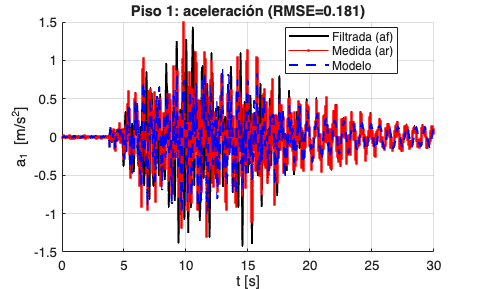

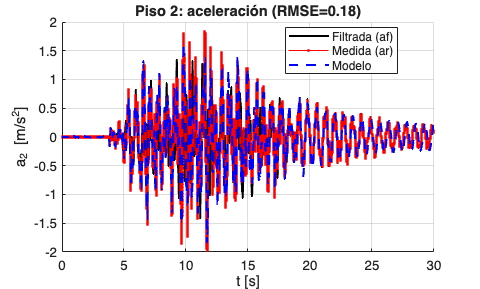

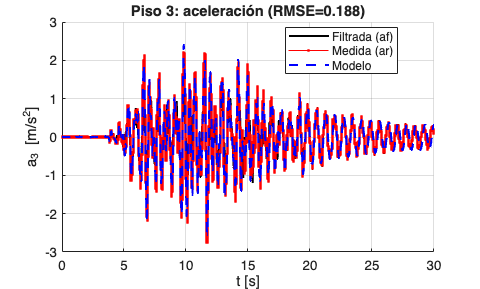

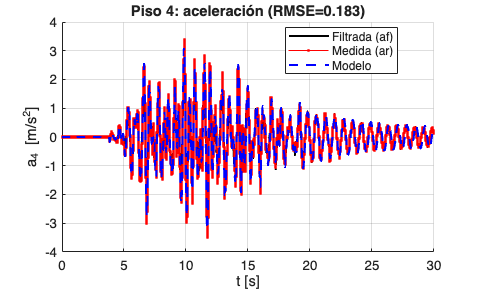

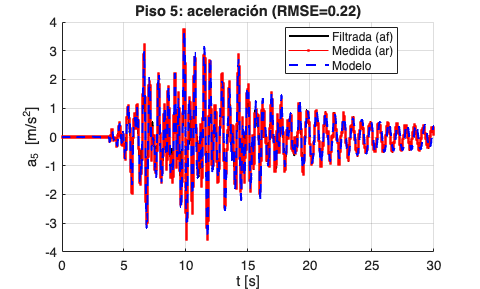


%% ========================= SIMULACIÓN FINAL (aceleración) ==============
[g_main, d_g] = mlp_heads(theta_star, Xn, lb2, ub2, unpack);
g_star = min(max(g_main + d_g, lb2), ub2);        % [k1..k5 c1..c5]

[~, ~, Arel] = simulate_building_no_mex_ACCEL(g_star, ab, t, M);  % aceleración relativa N×5

% Métricas por piso (aceleración)
n=5; MSE_a=zeros(1,n); RMSE_a=MSE_a; MAE_a=MSE_a; R2_a=MSE_a;
for i=1:n
    [MSE_a(i), RMSE_a(i)] = metrics(Arel(:,i), ar(:,i));
    MAE_a(i) = mean(abs(Arel(:,i)-ar(:,i)),'omitnan');
    R2_a(i)  = safe_r2(Arel(:,i), ar(:,i));
end

%% ========================= GRÁFICAS ====================================
for piso=1:5
    figure('Name',sprintf('Piso %d - aceleración',piso));
    hold on; grid on;
    % NEGRA: af últimas 5 columnas
    plot(t, AF5(:,piso), '-k', 'LineWidth', 1.4);
    % ROJA: medida
    plot(t, ar(:,piso), '.-r', 'MarkerSize', 6);
    % AZUL: modelo
    plot(t, Arel(:,piso), '--b', 'LineWidth', 1.6);

    xlabel('t [s]'); ylabel(sprintf('a_%d [m/s^2]',piso));
    legend('Filtrada (af)','Medida (ar)','Modelo','Location','best');
    title(sprintf('Piso %d: aceleración (RMSE=%.3g)',piso,RMSE_a(piso)));
end

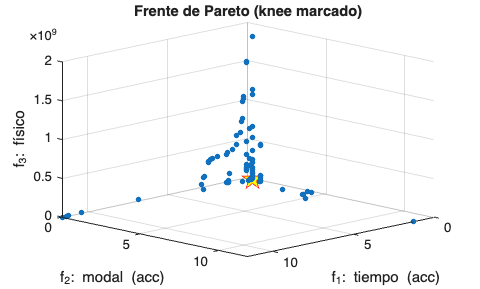


% Frente de Pareto
figure('Name','Frente de Pareto 3D');
plot3(Fpareto(:,1), Fpareto(:,2), Fpareto(:,3), '.','MarkerSize',12); grid on; hold on;
plot3(Fpareto(idxKnee,1),Fpareto(idxKnee,2),Fpareto(idxKnee,3),'rp','MarkerSize',16,'MarkerFaceColor','y');
xlabel('f_1: tiempo (acc)'); ylabel('f_2: modal (acc)'); zlabel('f_3: físico');
title('Frente de Pareto (knee marcado)'); view(135,20);


%% ========================= IMPRESIÓN DE COEFICIENTES ===================
k = g_star(1:5).'; c = g_star(6:10).';
disp('--- Coeficientes óptimos ---');

--- Coeficientes óptimos ---


disp(array2table([k c], 'VariableNames', ...
    {'k1','k2','k3','k4','k5','c1','c2','c3','c4','c5'}));

      k1        k2        k3       k4       k5        c1       c2       c3        c4        c5  
    ______    ______    ______    ____    ______    ______    ____    ______    ______    ______

    8547.1    8405.4    8509.7    8632    8680.5    21.161    23.6    21.247    17.874    19.302




%% ========================= GUARDADO ====================================
net.theta   = theta_star(:);
net.dims    = struct('D',D,'H1',H1,'H2',H2,'ny_main',ny_main,'ny_res',ny_res);
net.scaling = struct('mu_x',mu_x,'sig_x',sig_x,'lb',lb2,'ub',ub2);
net.misc    = struct('g_seed',g_seed,'Aineq',Aineq,'bineq',bineq);

save('EANN_MO_Q1_accel_result.mat', ...
    'net','g_star','ThetaPareto','Fpareto','idxKnee','Fknee_n','w', ...
    'M','t','Arel','ar','AF5','-v7.3');

disp('Archivo guardado: EANN_MO_Q1_accel_result.mat');

Archivo guardado: EANN_MO_Q1_accel_result.mat



%% ========================= SUBFUNCIONES ================================

function [Xfeat, mu, sig] = make_features_from_A5(A5, NLAGS)
% Convierte A5 (N×5) en un vector de características fijo:
%  • para cada columna: últimos NLAGS samples + 4 stats (RMS, energía,
%    curtosis, asimetría). Resultado: D = 5*(NLAGS+4).
    N = size(A5,1);
    L = min(NLAGS, N);
    tail = A5(end-L+1:end, :);                % L×5
    % Relleno si N<NLAGS
    if L < NLAGS
        tail = [zeros(NLAGS-L,5); tail];
        L = NLAGS;
    end
    feats = [];
    for j=1:5
        x = A5(:,j);
        xlags = tail(:,j);                    % NLAGS×1 (últimos)
        stats = [rms(x); sum(x.^2); kurtosis(x); skewness(x)];
        feats = [feats; xlags; stats];       %#ok<AGROW>
    end
    Xfeat = feats;                            % D×1
    mu  = mean(Xfeat);
    sig = std(Xfeat);
end

function wt = time_weights_from_ab(ab)
% Peso temporal (0.3..1) proporcional a la energía de la entrada.
    p = ab.^2; p = p - min(p); p = p / max(p + eps);
    wt = 0.3 + 0.7*p;
end

function theta_seed = make_theta_seed(g_seed, lb, ub, pack, W1z, b1z, W2z, b2z, W3z, W3bz, b3bz)
% Construye un cromosoma theta cuya cabeza principal imprime g_seed.
    g01 = (g_seed - lb) ./ (ub - lb);
    g01 = min(max(g01, 1e-6), 1 - 1e-6);
    z3  = 2*g01 - 1;
    b3z = atanh(z3);
    theta_seed = pack(W1z, b1z, W2z, b2z, W3z, b3z, W3bz, b3bz);
    theta_seed = theta_seed(:).';
end

function [g_main, d_g] = mlp_heads(theta, xfeat, lb, ub, unpack)
% Pasa xfeat por la red y mapea a [lb,ub]; residual ±15%.
    [W1,b1,W2,b2,W3,b3,W3b,b3b] = unpack(theta);
    z1 = tanh(W1*xfeat + b1);
    z2 = tanh(W2*z1 + b2);
    z_main = tanh(W3*z2 + b3);
    z_res  = tanh(W3b*z2 + b3b);
    g01 = (z_main + 1)/2;
    g_main = lb + (ub - lb).*g01;
    d_g = 0.15 .* g_main .* z_res;
end

function [X,V,Arel] = simulate_building_no_mex_ACCEL(g, ab, t, M)
% Integra por Tustin y devuelve desplazamiento (X), velocidad (V)
% y ACELERACIÓN RELATIVA (Arel) por piso.
    k1=g(1);k2=g(2);k3=g(3);k4=g(4);k5=g(5);
    c1=g(6);c2=g(7);c3=g(8);c4=g(9);c5=g(10);
    n=5; Mi = inv(M); l = ones(n,1);
    C=[c1+c2,-c2,0,0,0; -c2,c2+c3,-c3,0,0; 0,-c3,c3+c4,-c4,0; 0,0,-c4,c4+c5,-c5; 0,0,0,-c5,c5];
    K=[k1+k2,-k2,0,0,0; -k2,k2+k3,-k3,0,0; 0,-k3,k3+k4,-k4,0; 0,0,-k4,k4+k5,-k5; 0,0,0,-k5,k5];
    A=[zeros(n) eye(n); -Mi*K -Mi*C]; B=[zeros(n,1); -l];

    dt=t(2)-t(1); I=eye(2*n);
    Ad=(I-0.5*dt*A)\(I+0.5*dt*A);
    Bd=(I-0.5*dt*A)\(dt*B);

    N=numel(t); x=zeros(2*n,1);
    X=zeros(N,n); V=zeros(N,n); Arel=zeros(N,n);

    for k=1:N
        % guardar estado actual
        X(k,:) = x(1:n).';
        V(k,:) = x(n+1:end).';
        % a_rel = -M^{-1}(C v + K x) - l * ab(k)
        Arel(k,:) = (-Mi*(C*x(n+1:end) + K*x(1:n)) - l*ab(k)).';
        % actualizar
        x = Ad*x + Bd*ab(k);
    end
end

function F = fitness_multi_ACCEL(theta, A5, ar, ab, t, Xn, ...
    lb, ub, A, b, M, unpack, g_seed, ...
    w_time, KFFT, band, lambda_lin, lambda_smooth, lambda_log)
% Objetivos sobre ACELERACIÓN (tiempo + modo) + regularización física.
    [g_main, d_g] = mlp_heads(theta, Xn, lb, ub, unpack);
    g = min(max(g_main + d_g, lb), ub);

    [~,~,Arel] = simulate_building_no_mex_ACCEL(g, ab, t, M);  % N×5

    % f1: error temporal ponderado en aceleración
    n=5; f1=0; wt = w_time(:); wt = wt/mean(wt);
    for i=1:n
        ea = Arel(:,i) - ar(:,i);
        f1 = f1 + mean((ea.^2).*wt);    % MSE ponderado
    end

    % f2: desalineación modal (picos) en aceleración (pisos 1 y 2)
    dt = mean(diff(t)); fs = 1/dt;
    Nsig = size(Arel,1);
    win  = 0.5 - 0.5*cos(2*pi*(0:Nsig-1)'/(Nsig-1));
    [Sa1,fgrid] = spec_fft(ar(:,1).*win,  KFFT, fs);
    [Sy1,~]     = spec_fft(Arel(:,1).*win, KFFT, fs);
    [Sa2,~]     = spec_fft(ar(:,2).*win,  KFFT, fs);
    [Sy2,~]     = spec_fft(Arel(:,2).*win, KFFT, fs);

    fa = top2peaks(fgrid, Sa1) + top2peaks(fgrid, Sa2);
    fy = top2peaks(fgrid, Sy1) + top2peaks(fgrid, Sy2);
    fa = fa/2; fy = fy/2;
    f2 = sum((fa - fy).^2);

    % f3: físico
    viol = A*g - b;
    pen_lin = sum(max(viol,0).^2);
    dk = diff(g(1:5)); dc = diff(g(6:10));
    pen_smooth = sum(dk.^2) + sum(dc.^2);
    gpos = max(g, 1e-6);
    pen_log = sum( (log(gpos) - log(g_seed)).^2 );
    f3 = lambda_lin*pen_lin + lambda_smooth*pen_smooth + lambda_log*pen_log;

    F = [f1, f2, f3];
end

function [Pxx, f] = spec_fft(x, KFFT, fs)
% Periodograma lado único, puro MATLAB.
    x = x(:);  N = numel(x);
    X  = fft(x, KFFT);
    Px2 = (abs(X).^2) / (N*fs + eps);
    if mod(KFFT,2)==0, K2 = KFFT/2 + 1; else, K2 = (KFFT+1)/2; end
    Pxx = Px2(1:K2);
    if K2>2, Pxx(2:end-1) = 2*Pxx(2:end-1); end
    f = (0:K2-1).' * (fs / KFFT);
end

function fx = top2peaks(fgrid, S)
% Devuelve frecuencias de los 2 picos más altos (fallback sin findpeaks).
    [~, idx] = sort(S(:), 'descend');
    idx = unique(idx,'stable');
    if numel(idx) >= 2
        f = sort(fgrid(idx(1:2)));
    elseif numel(idx) == 1
        f = [fgrid(idx(1)); fgrid(idx(1))];
    else
        f = [fgrid(1); fgrid(1)];
    end
    fx = f(:).';
end

function [idxKnee, Fknee_n, scales] = select_knee(F)
% Rodilla por distancia a utopía en espacio normalizado.
    Fmin = min(F,[],1); Fmax = max(F,[],1);
    scales = Fmax - Fmin + eps;
    Fn = (F - Fmin)./scales;
    d  = sqrt(sum(Fn.^2,2));
    [~, idxKnee] = min(d);
    Fknee_n = Fn(idxKnee,:);
end

function r2 = safe_r2(yhat, y)
    yhat = yhat(:); y = y(:);
    ok = isfinite(yhat) & isfinite(y);
    yhat = yhat(ok); y = y(ok);
    if numel(y) < 3 || all(abs(y - mean(y)) < 1e-12)
        r2 = NaN; return;
    end
    ss_res = sum((y - yhat).^2);
    ss_tot = sum((y - mean(y)).^2) + eps;
    r2 = 1 - ss_res/ss_tot;
end
toc

Elapsed time is 831.052676 seconds.
